# Black-box Reliability Challenge 2019

% addpath('/Users/marco/Git/github/OpenCossan/COSSANXengine/src/common'); OpenCossan
% addpath('/Users/sghestra/Desktop/Cossan/OpenCossan'); OpenCossan% 
% no = false;
% yes = true;

# RP14 - Target: pF=7.52 1e-3, beta=2.42

SID: 1 - PID: 1

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T150345
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


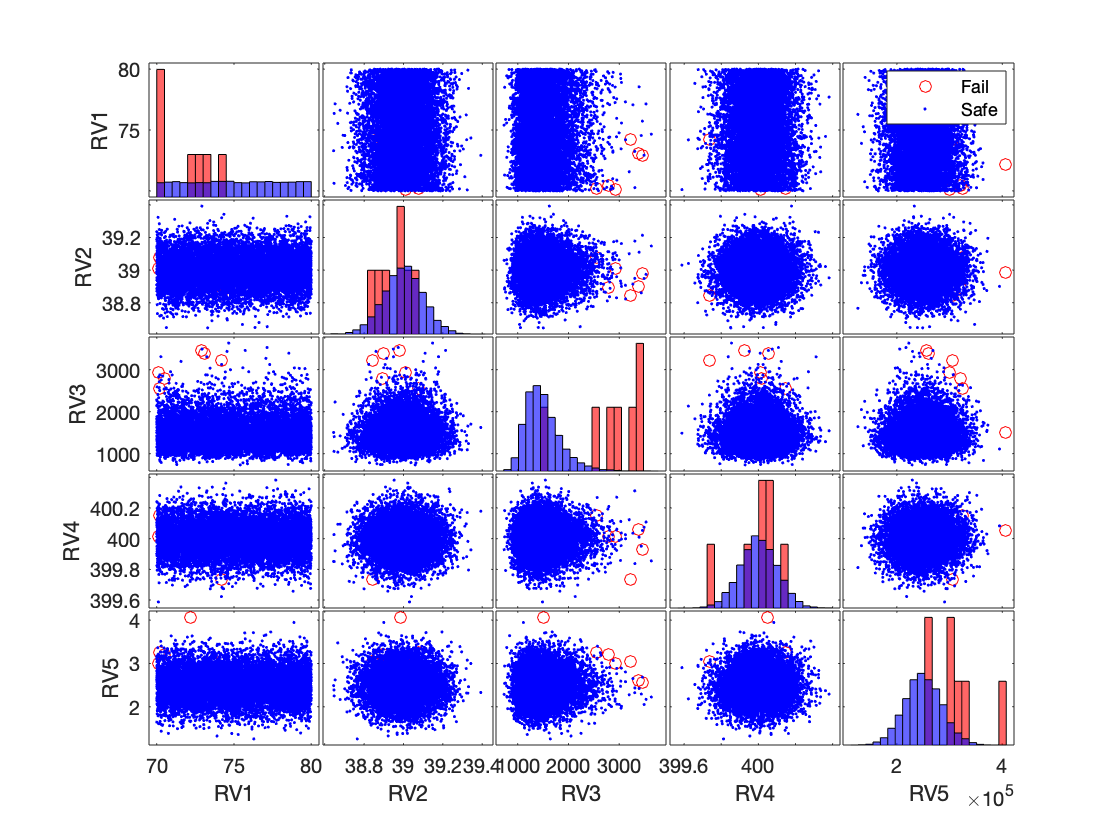

specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP14');

beta

beta = 3.1947

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 7.000e-04
*** Std       = 2.645e-04
*** CoV       = 3.779e-01
** Second Moment
*** variance  = 6.996e-04
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 8
** RV1; RV2; RV3; RV4; RV5; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150345


## Line Sampling

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
20 lines created 
[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T150346
Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


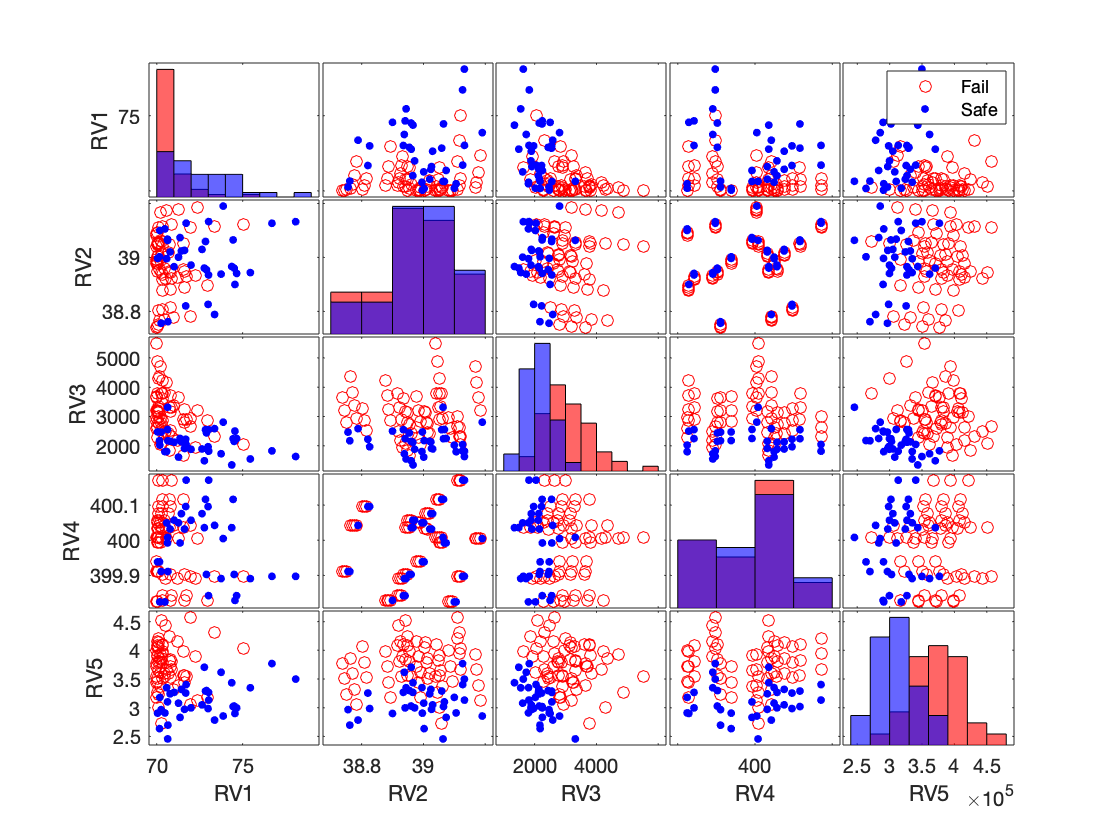

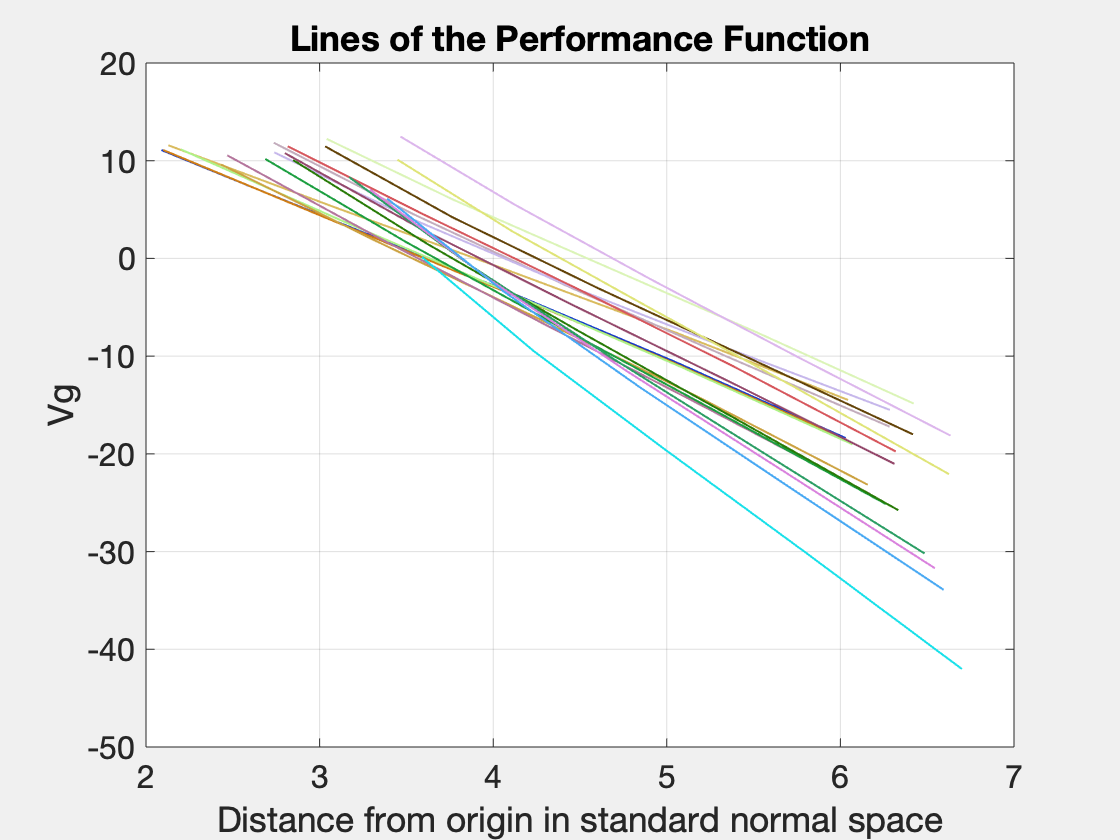

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',20,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4,5,6],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP14');

beta

beta = 2.9155

XpF

FailureProbability Object  -  Description: 
* Results obtained with LineSampling method
** First Moment
*** Pfhat     = 1.775e-03
*** Std       = 1.095e-03
*** CoV       = 6.167e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.000e+02
*** # batches  =         1
*** # lines    =        20
*** Exit Flag = Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


Xoutput

LineSamplingOutput Object  - Description: 
* Number of Variables: 8
** RV1; RV2; RV3; RV4; RV5; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 100
* Exit Flag: Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100
* Number of lines: 20
* Evaluation Points: 100


## Adaptive Line Sampling

AdaptiveLineSampling: Initialise Important Direction
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
AdaptiveLineSampling: Check inputs
AdaptiveLineSampling: Compute reliability index
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[AdvancedLineSampling:computeFailureProbability] Start AdaptiveLineSampling analysis
15 lines initialized 
* Starting analysis on line:1/15
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
* Starting analysis on line:2/15
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       *

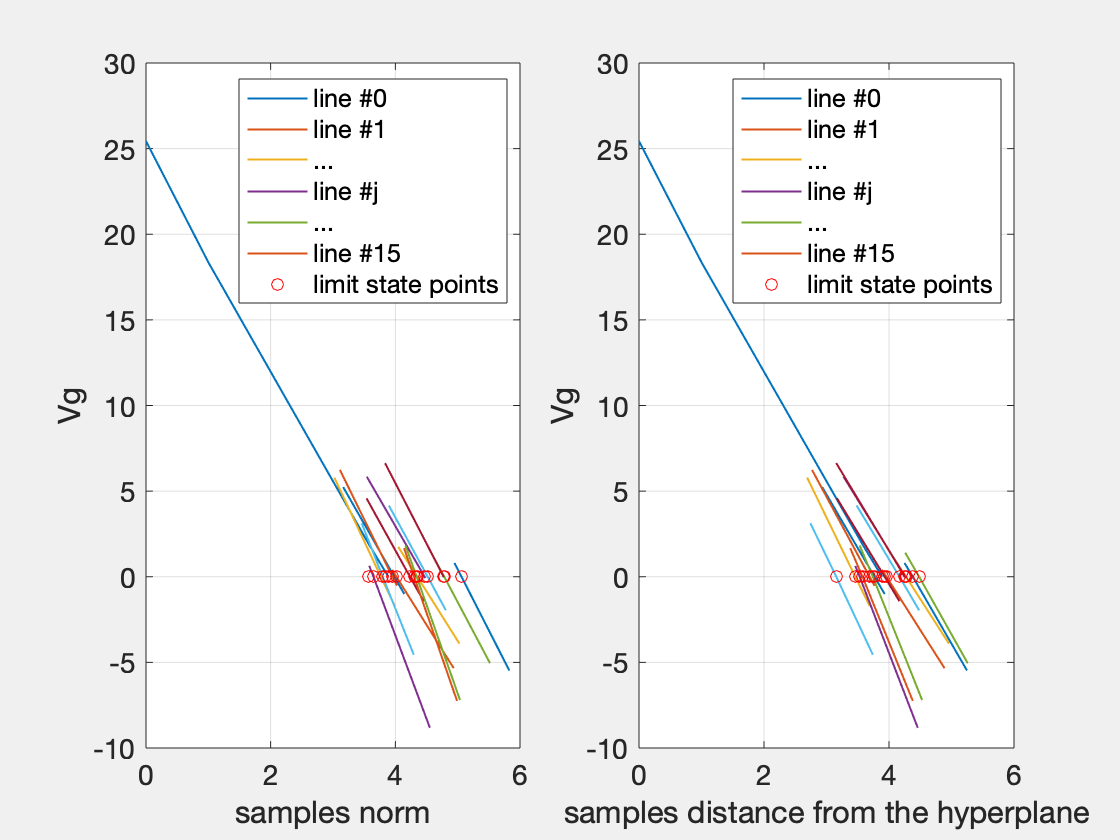

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


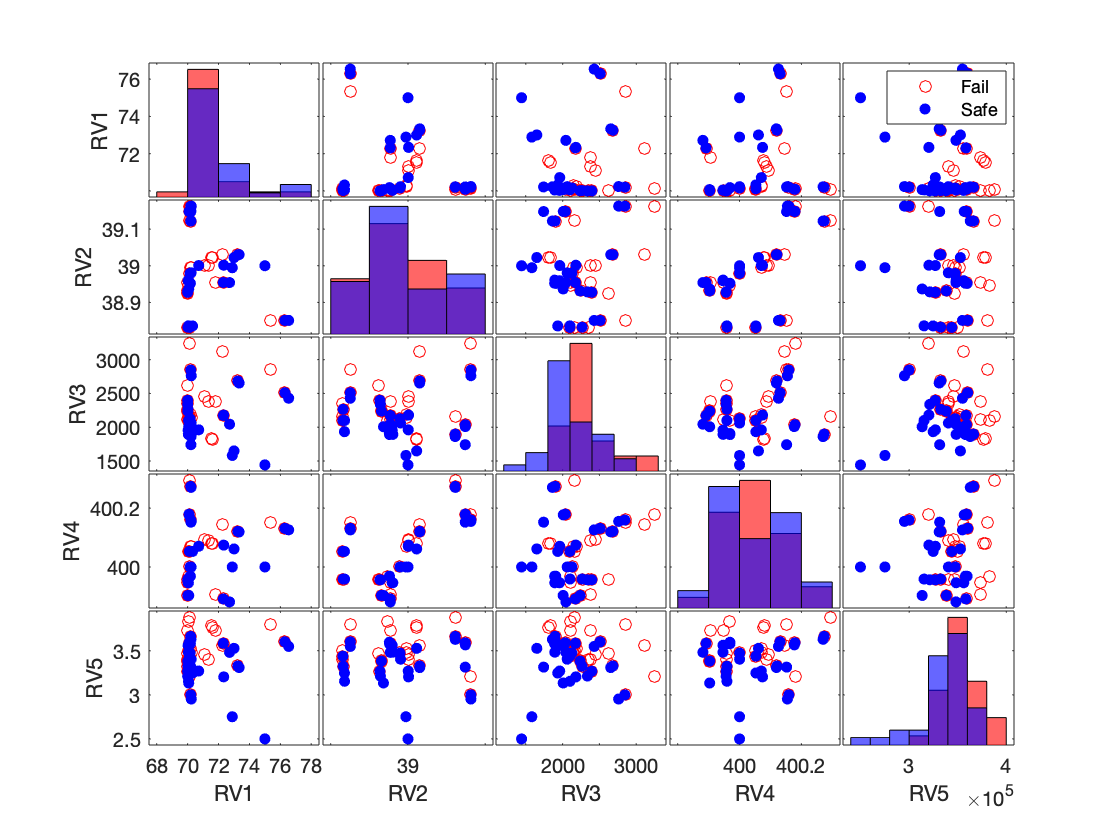

specs = struct(...
    'SimType','ALS',...
    'N',15,...
    ...'Vset',[0.5,1,2,3,5],...
    ...'Vset',[2,3,4,5,6],...
    ...'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP14');

beta

beta = 3.6624

XpF

FailureProbability Object  -  Description: 
* Results obtained with AdaptiveLineSampling method
** First Moment
*** Pfhat     = 1.249e-04
*** Std       = 5.272e-05
*** CoV       = 4.221e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 6.900e+01
*** # batches  =         1
*** # lines    =        15
*** Exit Flag = Maximum no. of lines reached. Lines computed 15; Max Lines : 15


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 8
** RV1; RV2; RV3; RV4; RV5; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 69
* Values stored in a matrix and structure format
* Exit Flag: Maximum no. of lines reached. Lines computed 15; Max Lines : 15
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150349


# RP24 - Target: 2.86 1e-3, beta=2.76

Set id: 1, Problem id: 2

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T150352
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


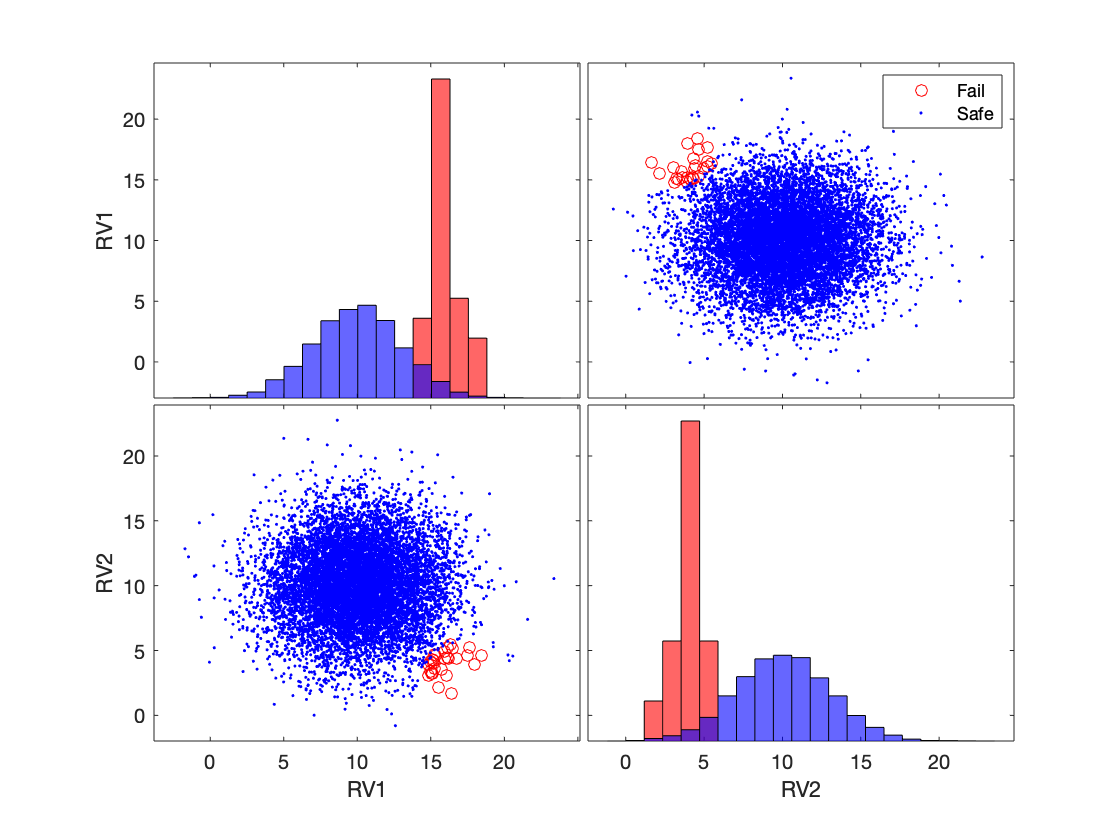

specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP24');

beta

beta = 2.7703

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 2.800e-03
*** Std       = 5.284e-04
*** CoV       = 1.887e-01
** Second Moment
*** variance  = 2.792e-03
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150352


## Line Sampling

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
20 lines created 
[Status:Evaluator  ]       * Processing solver 1/1
Intersection with the limit state function not found on Line: #16
Line: #16is entirely in the survival domain
Intersection with the limit state function not found on Line: #17
Line: #17is entirely in the survival domain
Intersection with the limit state function not found on Line: #18
Line: #18is entirely in the survival domain
Intersection with the limit state function not found on Line: #19
Line: #19is entirely in the survival domain
Intersection with the limit state function not found on Line: #20
Line: #20is entirely in the survival domain
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200

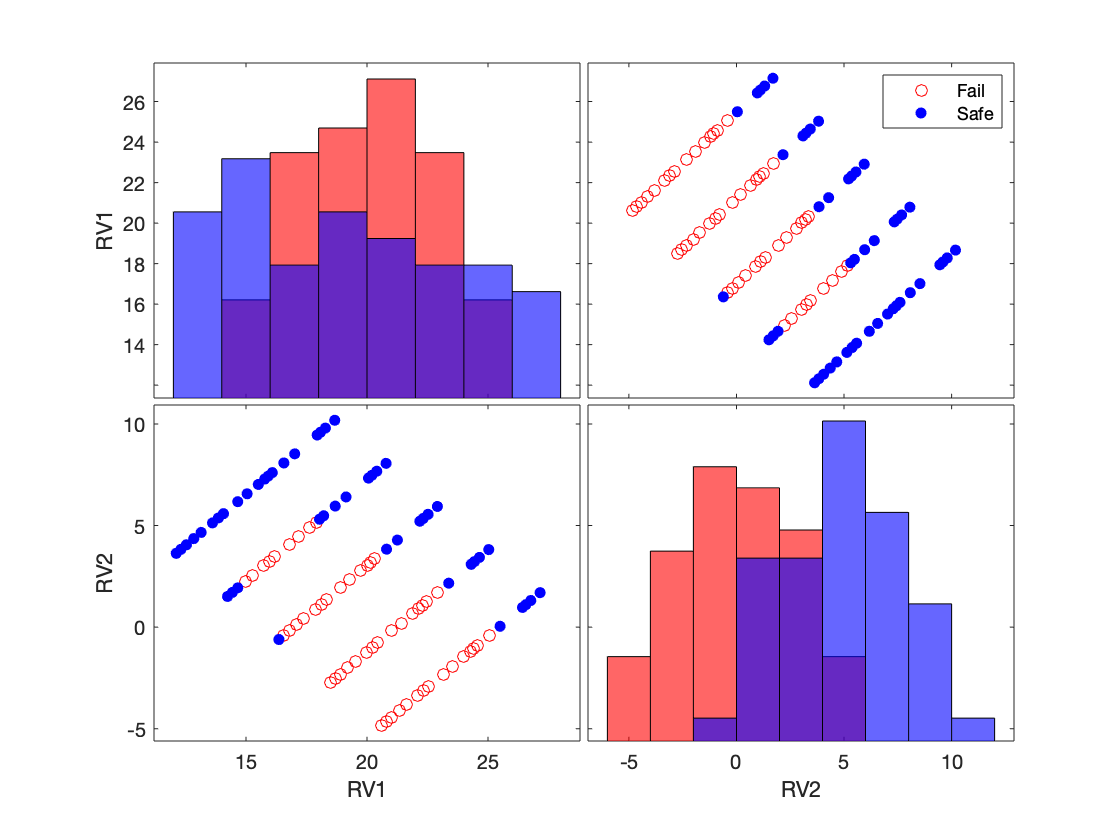

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',20,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4,5,6],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP24');

beta

beta = 2.8372

XpF

FailureProbability Object  -  Description: 
* Results obtained with LineSampling method
** First Moment
*** Pfhat     = 2.276e-03
*** Std       = 5.767e-04
*** CoV       = 2.534e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.000e+02
*** # batches  =         1
*** # lines    =        20
*** Exit Flag = Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


Xoutput

LineSamplingOutput Object  - Description: 
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 100
* Exit Flag: Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100
* Number of lines: 20
* Evaluation Points: 100


## Adaptive Line Sampling

AdaptiveLineSampling: Initialise Important Direction
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
AdaptiveLineSampling: Check inputs
AdaptiveLineSampling: Compute reliability index
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[AdvancedLineSampling:computeFailureProbability] Start AdaptiveLineSampling analysis
10 lines initialized 
* Starting analysis on line:1/10
[Status:Evaluator  ]       * Processing solver 1/1
Intersection found at first attempt on Line#:1
* Starting analysis on line:2/10
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
* Starting analysis on line:3/10
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
* Starting analysis on line:4/10
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator

[Status:Evaluator  ]       * Processing solver 1/1


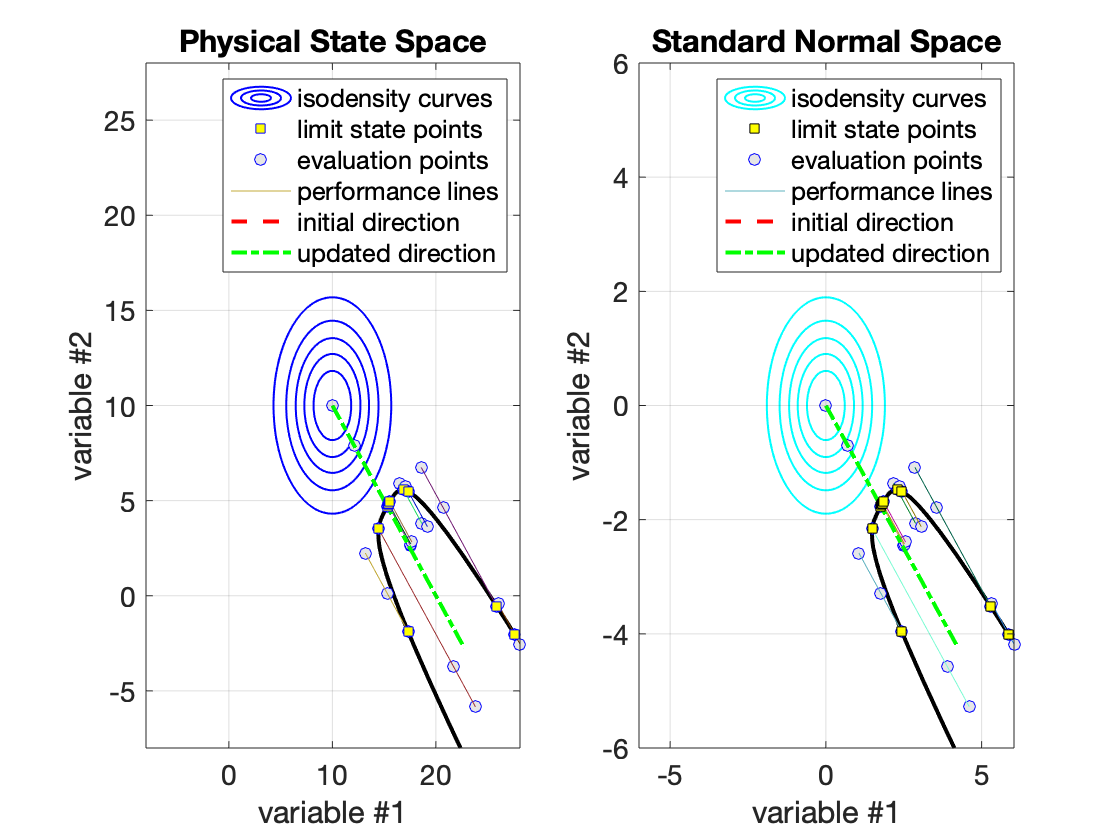

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


specs = struct(...
    'SimType','ALS',...
    'N',10,...
    ...'Vset',[0.5,1,2,3,5],...
    ...'Vset',[2,3,4,5,6],...
    ...'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP24');

beta

beta = 2.6847

XpF

FailureProbability Object  -  Description: 
* Results obtained with AdaptiveLineSampling method
** First Moment
*** Pfhat     = 3.630e-03
*** Std       = 8.753e-04
*** CoV       = 2.411e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 2.900e+01
*** # batches  =         1
*** # lines    =        10
*** Exit Flag = Maximum no. of lines reached. Lines computed 10; Max Lines : 10


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 29
* Values stored in a matrix and structure format
* Exit Flag: Maximum no. of lines reached. Lines computed 10; Max Lines : 10
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150354


# RP31 - Target: 1.80 1e-4, beta = 3.58

Set id: 1, Problem id: 4

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T150711
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


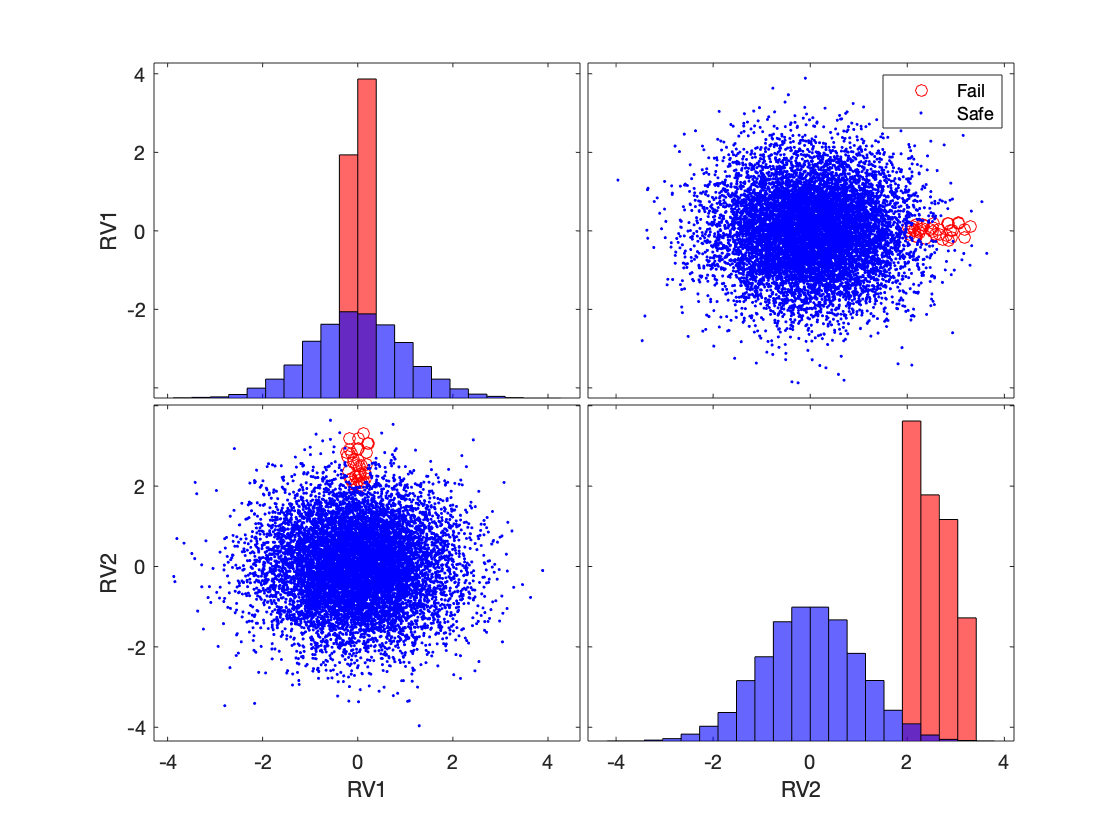

specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP31');

beta

beta = 2.6783

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 3.700e-03
*** Std       = 6.072e-04
*** CoV       = 1.641e-01
** Second Moment
*** variance  = 3.687e-03
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150711


## Line Sampling

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
20 lines created 
[Status:Evaluator  ]       * Processing solver 1/1
Intersection with the limit state function not found on Line: #4
Line: #4is entirely in the survival domain
Intersection with the limit state function not found on Line: #5
Line: #5is entirely in the survival domain
Intersection with the limit state function not found on Line: #6
Line: #6is entirely in the survival domain
Intersection with the limit state function not found on Line: #7
Line: #7is entirely in the survival domain
Intersection with the limit state function not found on Line: #8
Line: #8is entirely in the survival domain
Intersection with the limit state function not found on Line: #9
Line: #9is entirely in the survival domain
Intersection with the limit state

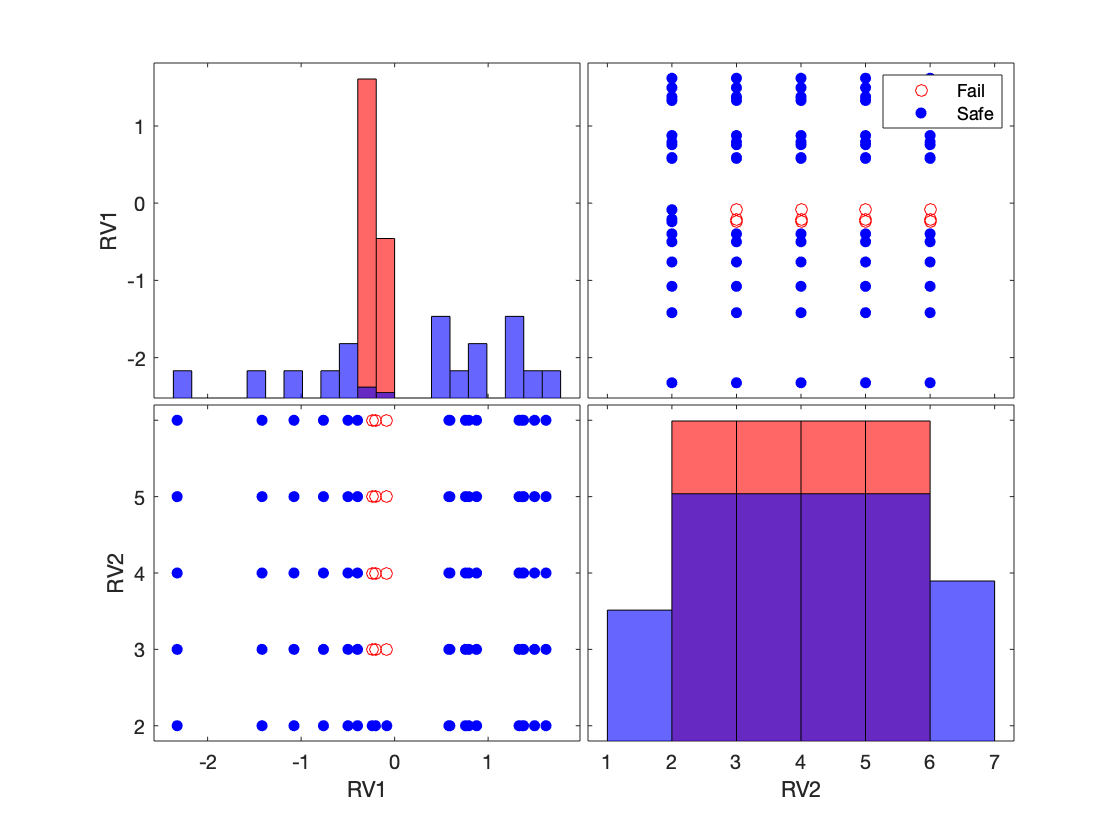

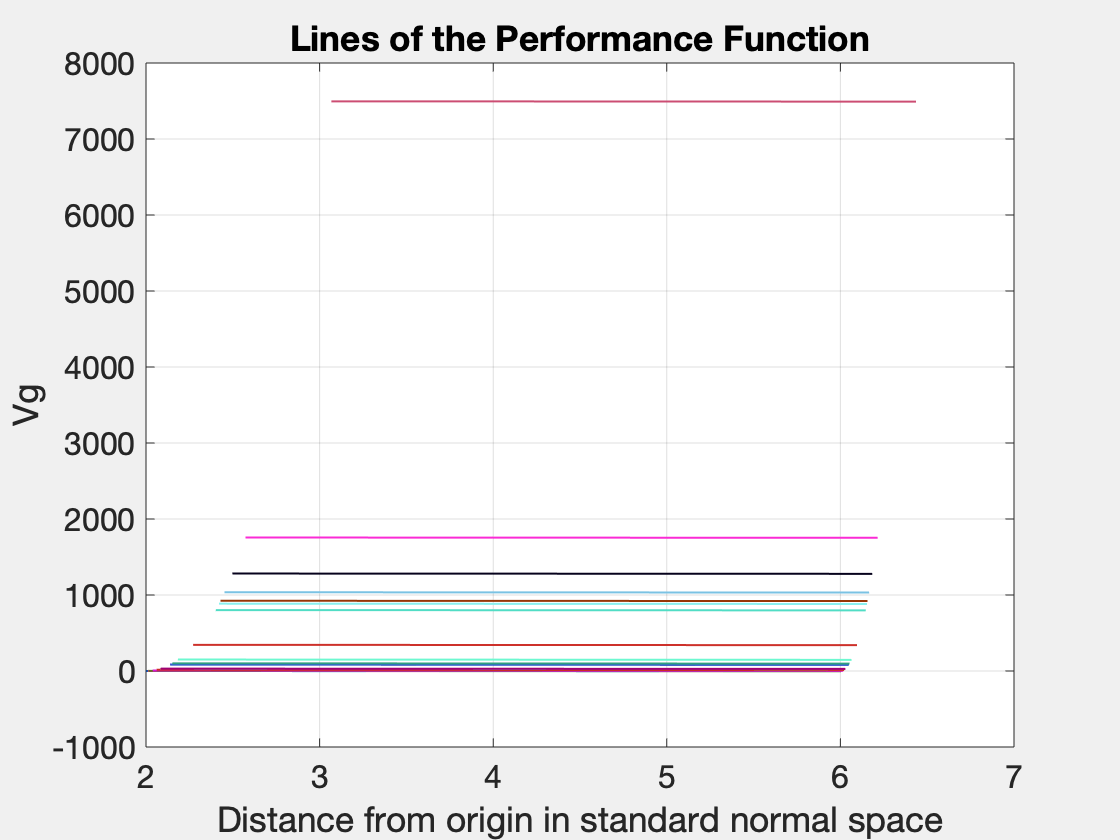

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',20,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4,5,6],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP31');

beta

beta = 2.9555

XpF

FailureProbability Object  -  Description: 
* Results obtained with LineSampling method
** First Moment
*** Pfhat     = 1.561e-03
*** Std       = 1.139e-03
*** CoV       = 7.298e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.000e+02
*** # batches  =         1
*** # lines    =        20
*** Exit Flag = Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


Xoutput

LineSamplingOutput Object  - Description: 
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 100
* Exit Flag: Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100
* Number of lines: 20
* Evaluation Points: 100


## Adaptive Line Sampling

AdaptiveLineSampling: Initialise Important Direction
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
AdaptiveLineSampling: Check inputs
AdaptiveLineSampling: Compute reliability index
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[AdvancedLineSampling:computeFailureProbability] Start AdaptiveLineSampling analysis
15 lines initialized 
* Starting analysis on line:1/15
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
* Starting analysis on line:2/15
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
* Starting analysis on line:3/15
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver

[Status:Evaluator  ]       * Processing solver 1/1


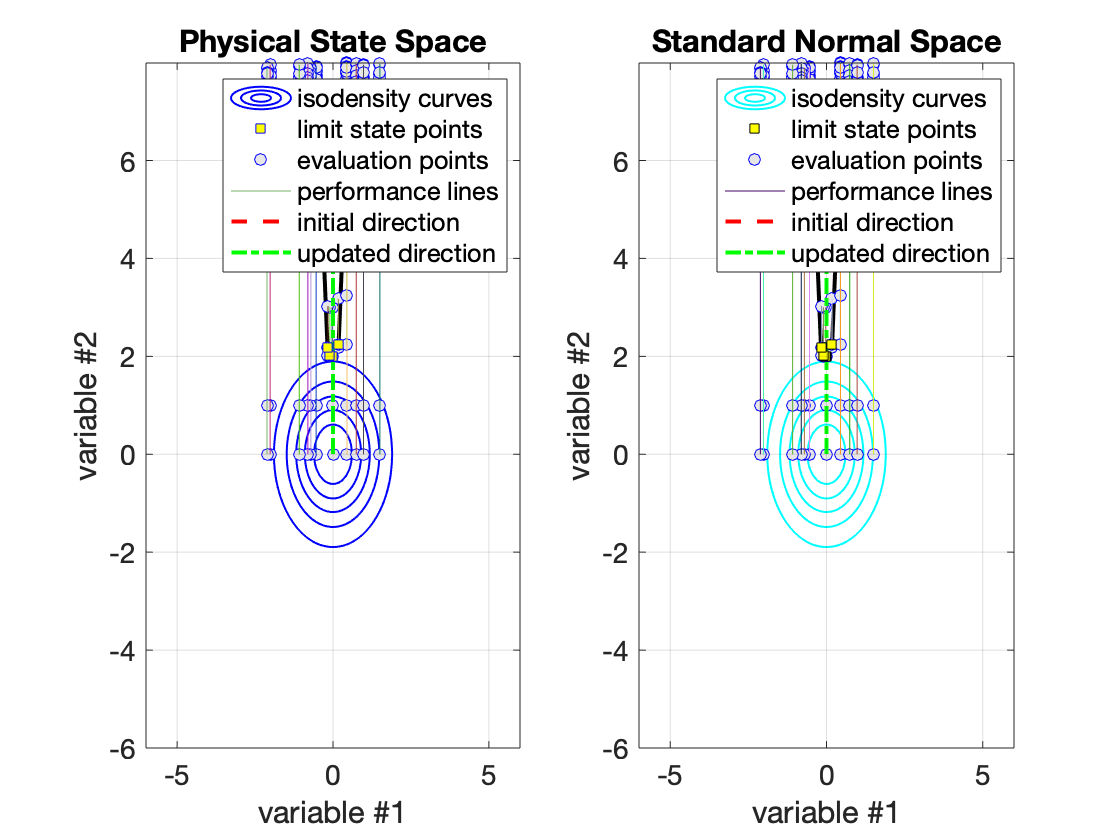

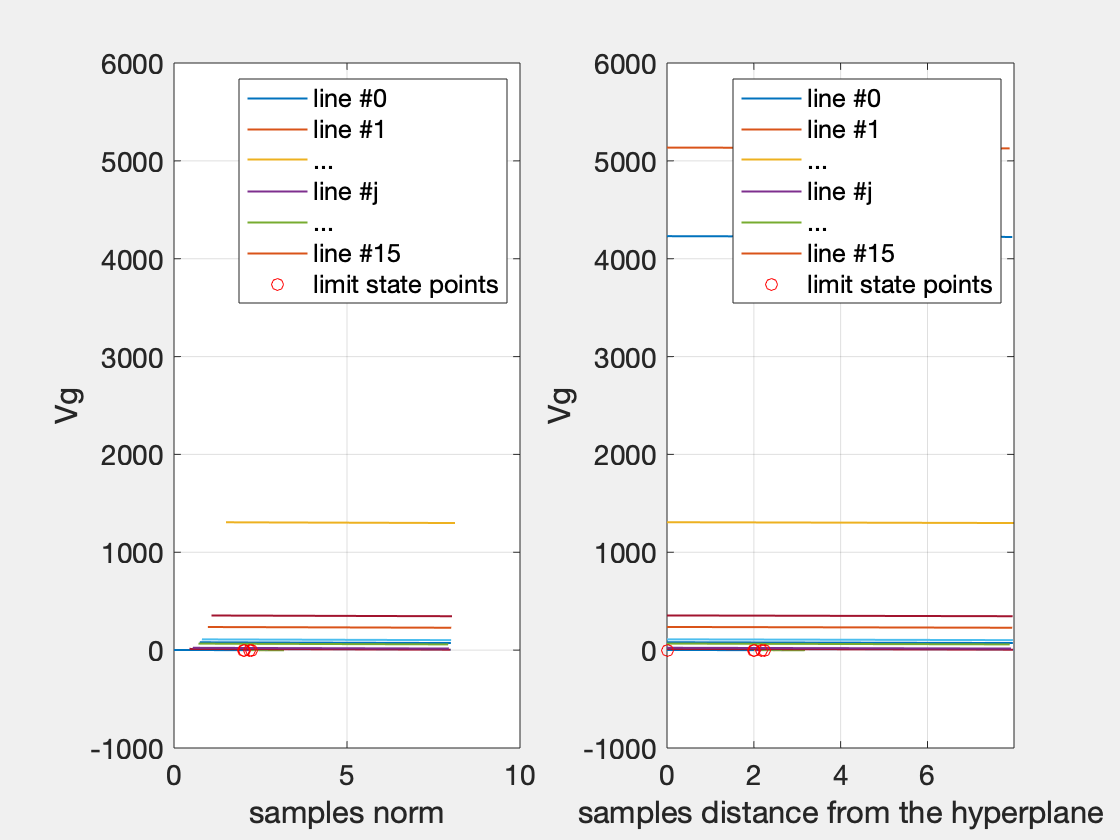

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 34
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


specs = struct(...
    'SimType','ALS',...
    'N',15,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP31');

beta

beta = -0.6375

XpF

FailureProbability Object  -  Description: 
* Results obtained with AdaptiveLineSampling method
** First Moment
*** Pfhat     = 7.381e-01
*** Std       = 1.161e-01
*** CoV       = 1.573e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.250e+02
*** # batches  =         1
*** # lines    =        15
*** Exit Flag = Maximum no. of lines reached. Lines computed 15; Max Lines : 15


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 125
* Values stored in a matrix and structure format
* Exit Flag: Maximum no. of lines reached. Lines computed 15; Max Lines : 15
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T150714


# RP53 - Target: 3.13 1e-2, beta = 1.86

Set id: 1, Problem id: 6

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T151236
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


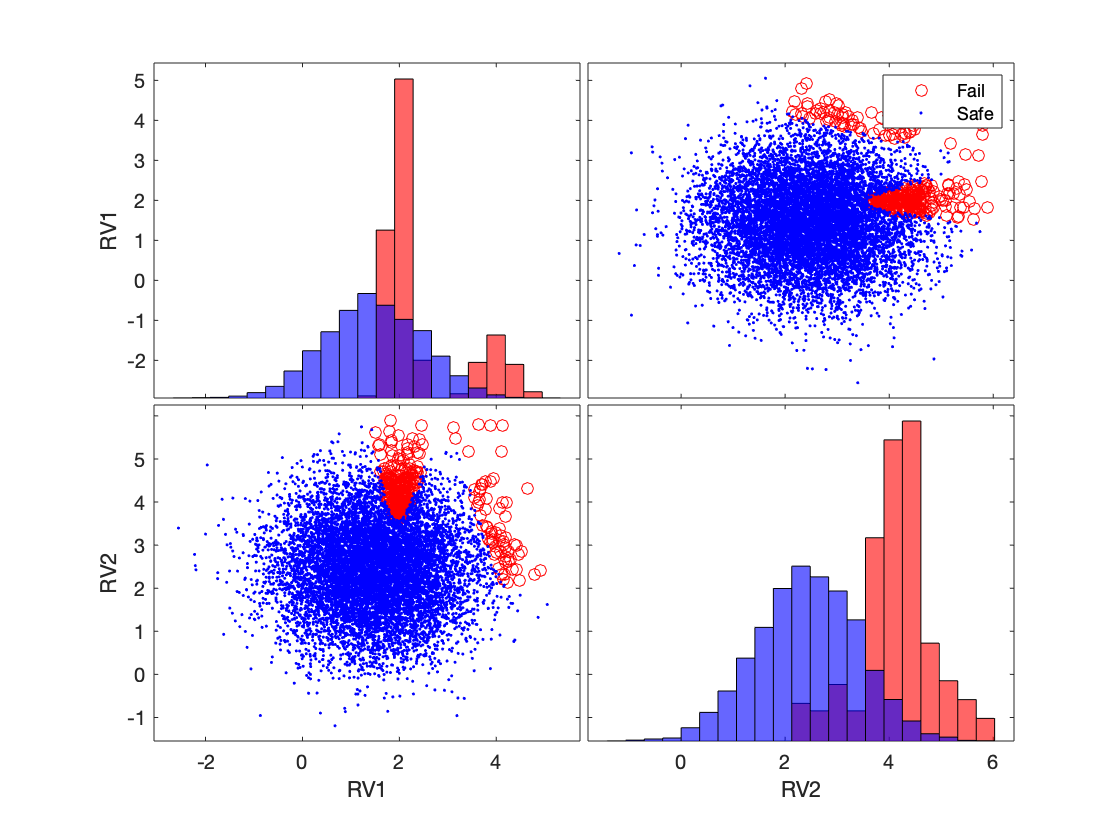

specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP53');

beta

beta = 1.8536

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 3.190e-02
*** Std       = 1.757e-03
*** CoV       = 5.509e-02
** Second Moment
*** variance  = 3.089e-02
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T151236


## Line Sampling

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
20 lines created 
[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T151237
Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


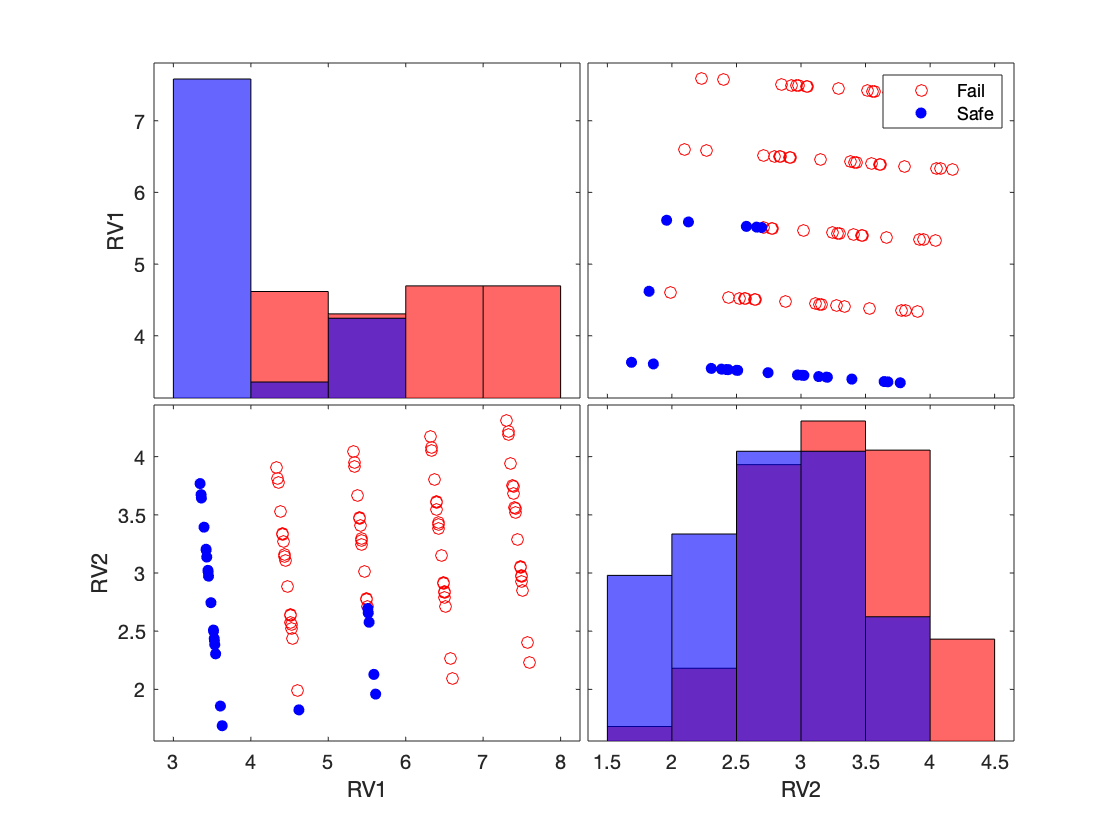

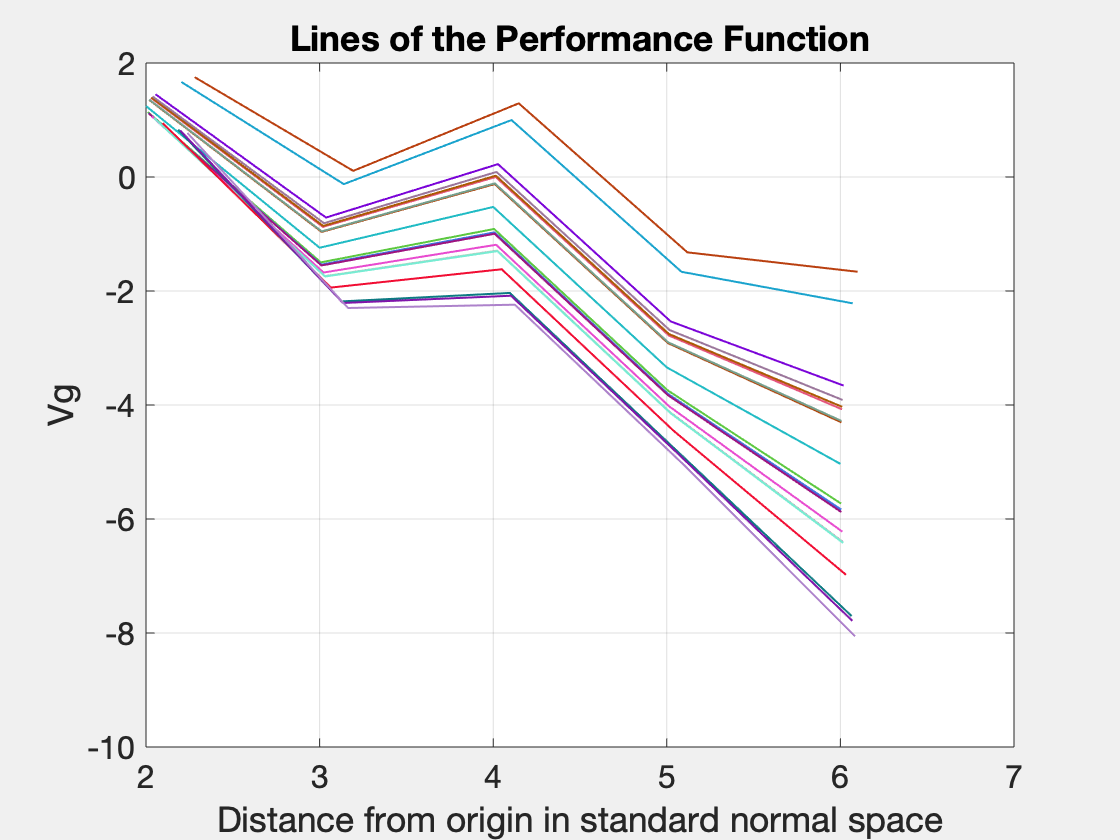

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 48
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',20,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4,5,6],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP53');

beta

beta = 2.2932

XpF

FailureProbability Object  -  Description: 
* Results obtained with LineSampling method
** First Moment
*** Pfhat     = 1.092e-02
*** Std       = 1.521e-03
*** CoV       = 1.393e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.000e+02
*** # batches  =         1
*** # lines    =        20
*** Exit Flag = Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


Xoutput

LineSamplingOutput Object  - Description: 
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 100
* Exit Flag: Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100
* Number of lines: 20
* Evaluation Points: 100


## Adaptive Line Sampling

AdaptiveLineSampling: Initialise Important Direction
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
AdaptiveLineSampling: Check inputs
AdaptiveLineSampling: Compute reliability index
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
Intersection on the line passing through the origin found with less accuracy than specified.
 May want to increase the number of evaluation points currently set to 10
[AdvancedLineSampling:computeFailureProbability] Start AdaptiveLineSampling analysis


[Status:Evaluator  ]       * Processing solver 1/1


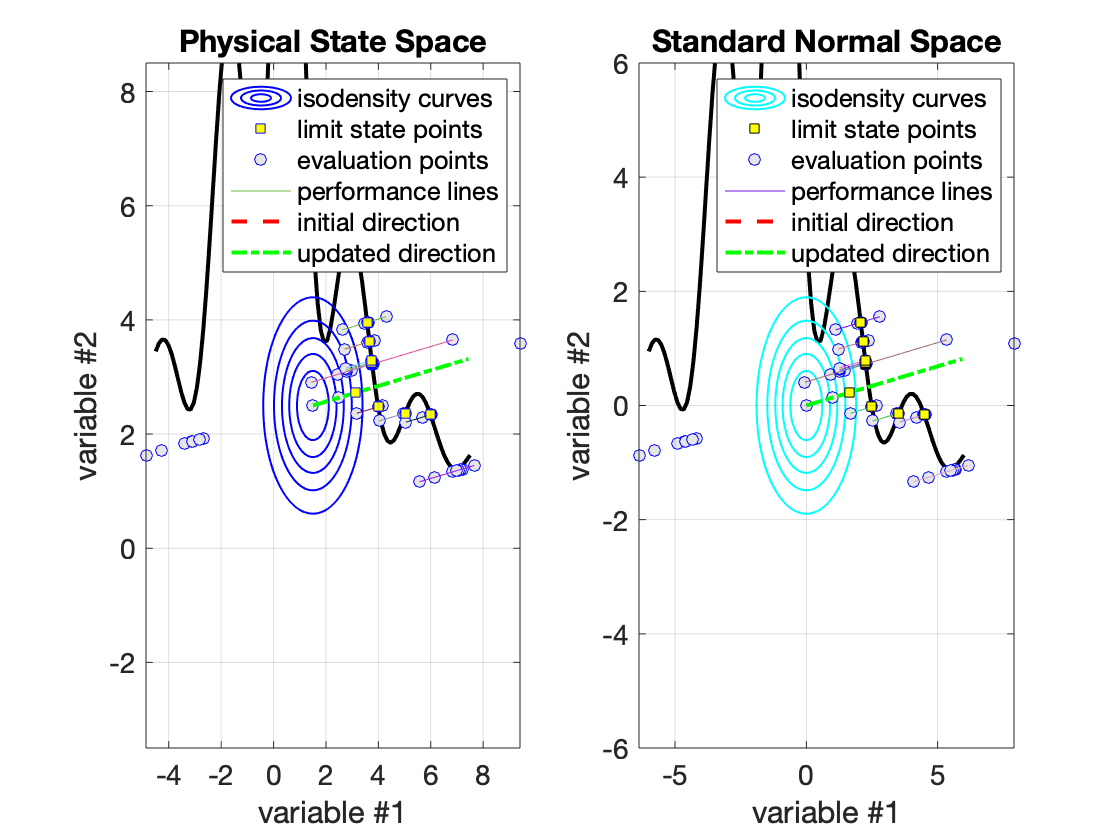

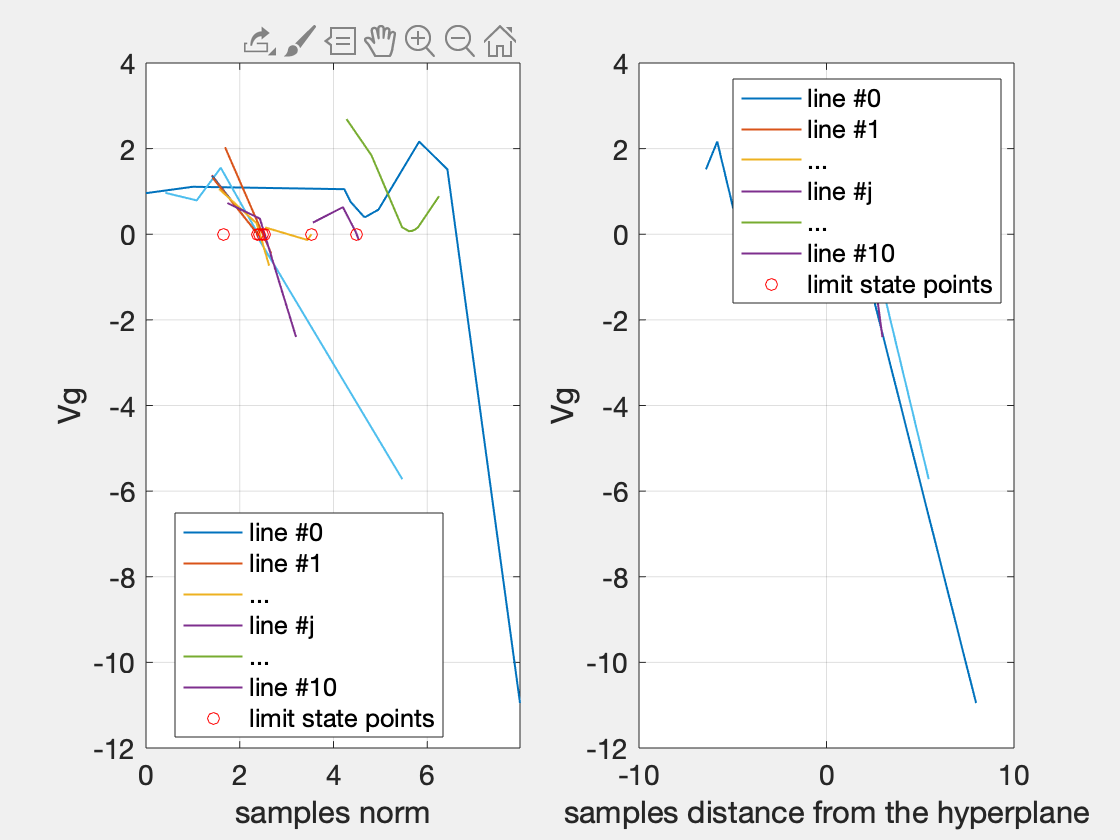

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 52
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


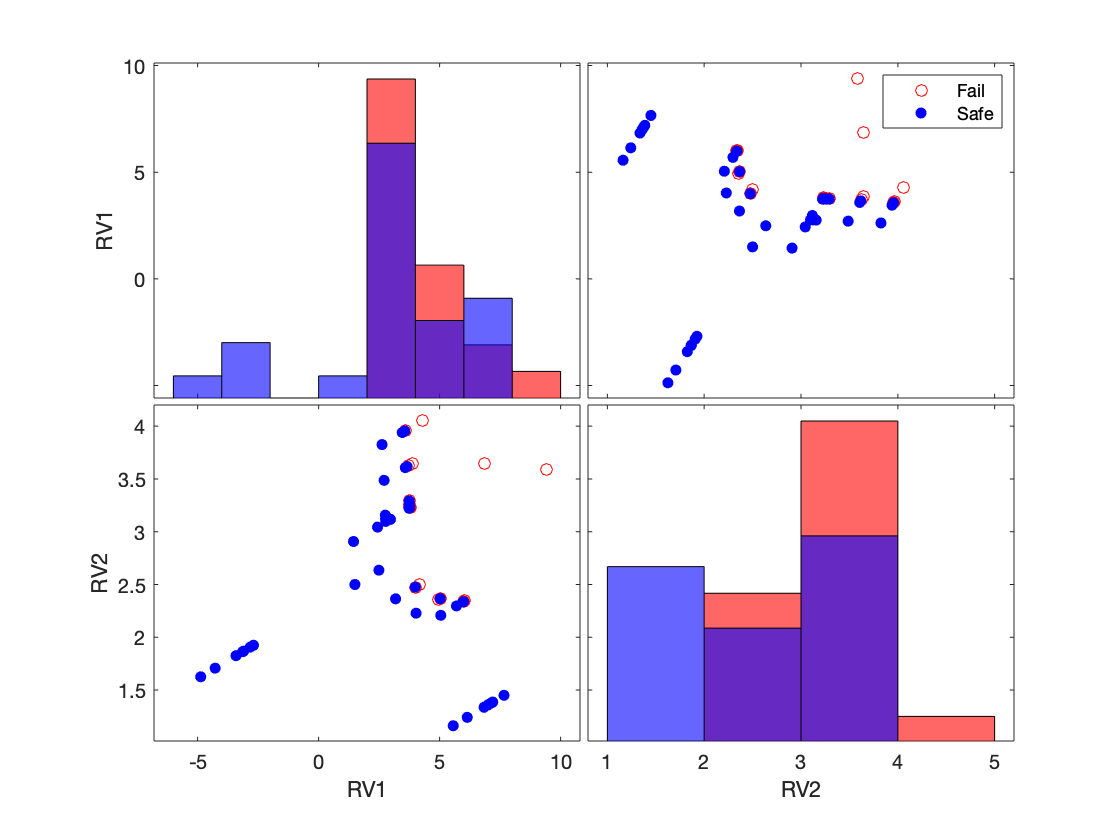

specs = struct(...
    'SimType','ALS',...
    'N',10,...
    ...'Vset',[0.5,1,2,3,5],...
    ...'Vset',[2,3,4,5,6],...
    ...'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP53');

beta

beta = 1.2431

XpF

FailureProbability Object  -  Description: 
* Results obtained with AdaptiveLineSampling method
** First Moment
*** Pfhat     = 1.069e-01
*** Std       = 9.924e-02
*** CoV       = 9.281e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 6.800e+01
*** # batches  =         1
*** # lines    =        10
*** Exit Flag = Maximum no. of lines reached. Lines computed 10; Max Lines : 10


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 68
* Values stored in a matrix and structure format
* Exit Flag: Maximum no. of lines reached. Lines computed 10; Max Lines : 10
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T151238


# RP54 - Target: 9.98 1e-4, beta = 3.09

Set id: 1, Problem id: 7

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T151422
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


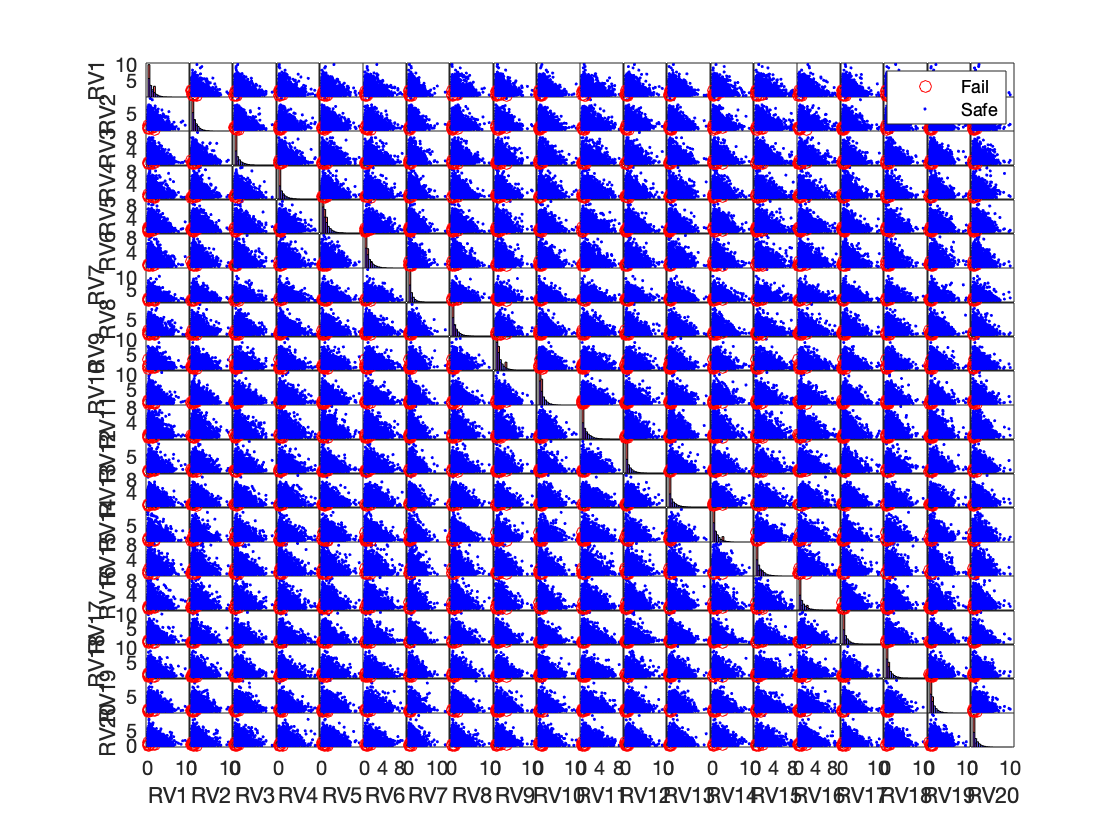

no = false;
yes = true;
specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP54');

beta

beta = 3.1214

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 9.000e-04
*** Std       = 2.999e-04
*** CoV       = 3.332e-01
** Second Moment
*** variance  = 8.993e-04
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 23
** RV1; RV2; RV3; RV4; RV5; RV6; RV7; RV8; RV9; RV10; RV11; RV12; RV13; RV14; RV15; RV16; RV17; RV18; RV19; RV20; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T151422


## Line Sampling

% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',20,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4,5,6],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP54');

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
20 lines created 
[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T151448
Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 64
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


beta

beta = 3.2208

XpF

FailureProbability Object  -  Description: 
* Results obtained with LineSampling method
** First Moment
*** Pfhat     = 6.391e-04
*** Std       = 1.698e-04
*** CoV       = 2.656e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 1.000e+02
*** # batches  =         1
*** # lines    =        20
*** Exit Flag = Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100


Xoutput

LineSamplingOutput Object  - Description: 
* Number of Variables: 23
** RV1; RV2; RV3; RV4; RV5; RV6; RV7; RV8; RV9; RV10; RV11; RV12; RV13; RV14; RV15; RV16; RV17; RV18; RV19; RV20; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 100
* Exit Flag: Maximum no. of samples reached. Samples computed 100; Maximum allowed samples: 100
* Number of lines: 20
* Evaluation Points: 100


## Adaptive Line Sampling

specs = struct(...
    'SimType','ALS',...
    'N',10,...
    ...'Vset',[0.5,1,2,3,5],...
    ...'Vset',[2,3,4,5,6],...
    ...'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP54');

AdaptiveLineSampling: Initialise Important Direction
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
AdaptiveLineSampling: Check inputs
AdaptiveLineSampling: Compute reliability index
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[AdvancedLineSampling:computeFailureProbability] Start AdaptiveLineSampling analysis
10 lines initialized 
* Starting analysis on line:1/10
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Ev

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 65
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


beta

beta = 3.3326

XpF

FailureProbability Object  -  Description: 
* Results obtained with AdaptiveLineSampling method
** First Moment
*** Pfhat     = 4.303e-04
*** Std       = 2.138e-04
*** CoV       = 4.969e-01
** Second Moment
*** variance  =       NaN
** Simulation details
*** # samples  = 5.800e+01
*** # batches  =         1
*** # lines    =        10
*** Exit Flag = Maximum no. of lines reached. Lines computed 10; Max Lines : 10


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 23
** RV1; RV2; RV3; RV4; RV5; RV6; RV7; RV8; RV9; RV10; RV11; RV12; RV13; RV14; RV15; RV16; RV17; RV18; RV19; RV20; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 58
* Values stored in a matrix and structure format
* Exit Flag: Maximum no. of lines reached. Lines computed 10; Max Lines : 10
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T151513


Operation terminated by user during gplotmatrix/gplotmatrixLabelCallback (line 581)

Error using matlab.internal.editor.figure.SerializedFigureState/serialize
Interrupt while evaluating Figure SizeChangedFcn.



# RP75 - Target: 1.07 1e-2, beta = 2.33

Set id: 1, Problem id: 9

## Monte Carlo

[Status:Evaluator  ]       * Processing solver 1/1
[Simulation:exportResults] Writing partial results (SimulationData_batch_1_of_1) on the folder: /Users/marco/Documents/MATLAB/20200221T151902
Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


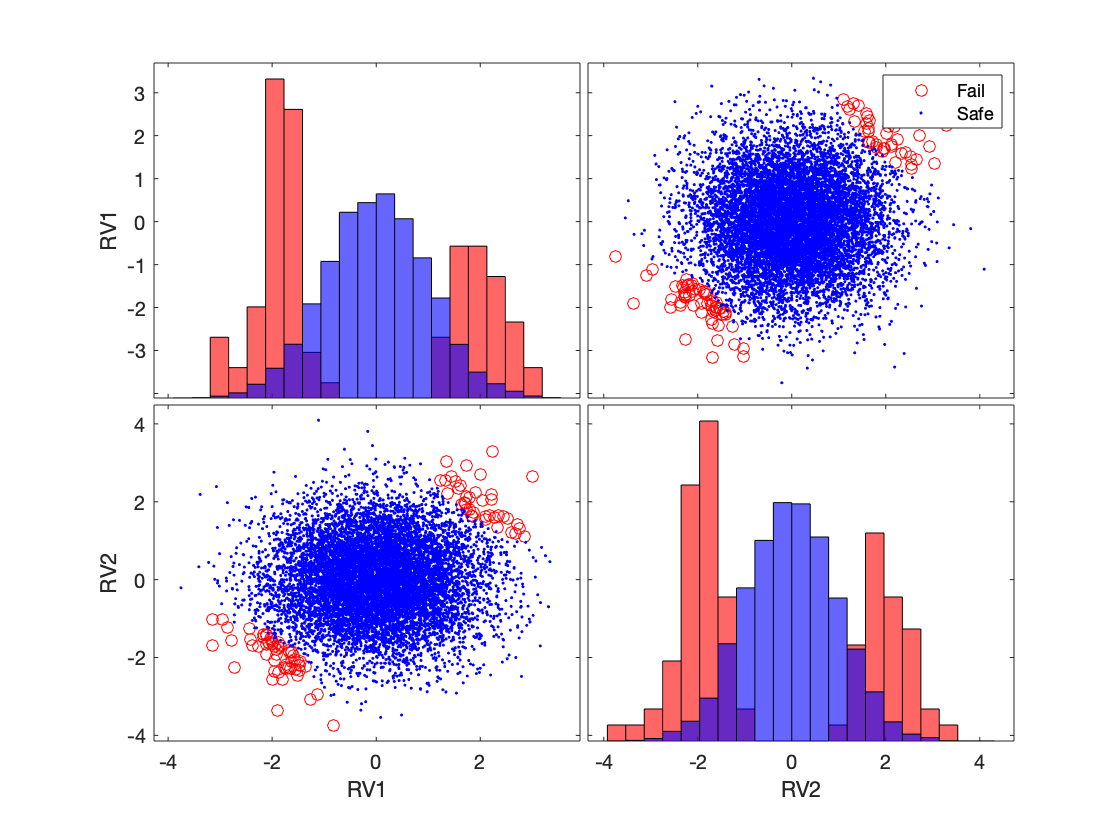

no = false;
yes = true;
specs = struct(...
    'SimType','MC',...
    'N',10000,...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP75');

beta

beta = 2.3455

XpF

FailureProbability Object  -  Description: 
* Results obtained with MonteCarlo method
** First Moment
*** Pfhat     = 9.500e-03
*** Std       = 9.701e-04
*** CoV       = 1.021e-01
** Second Moment
*** variance  = 9.411e-03
** Simulation details
*** # samples  = 1.000e+04
*** # batches  =         1
*** # lines    =         0
*** Exit Flag = Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000


Xoutput

SimulationData Object  - Description:  - apply(@evaluator) - apply(@Model) - apply(@ProbabilisticModel)
* Number of Variables: 5
** RV1; RV2; Xthreshold; out; Vg;
* Batch: 1 - Number of realizations: 10000
* Values stored in a structure format only
* Exit Flag: Maximum no. of samples reached. Samples computed 10000; Maximum allowed samples: 10000
* Batches stored in the folder: /Users/marco/Documents/MATLAB//20200221T151902


## Line Sampling

% ['IND','PHY','SNS']
specs = struct(...
    'SimType','LS',...
    'N',15,...
    ...'Vset',[0.5,1,2,3,5],...
    'Vset',[2,3,4],...
    'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP75');

[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[Status:Evaluator  ]       * Processing solver 1/1
[LineSampling:pf] Start LineSampling analysis
15 lines created 


Error using Samples/set.MsamplesHyperCube (line 502)
The hypercube sample values must be in the [0,1] range

Error in Samples (line 355)
                    Xobj.MsamplesHyperCube(:,irv+(1:Xobj.Xrvset{n}.Nrv))= ...

Error in 

beta
XpF
Xoutput

## Adaptive Line Sampling

specs = struct(...
    'SimType','ALS',...
    'N',10,...
    ...'Vset',[0.5,1,2,3,5],...
    ...'Vset',[2,3,4,5,6],...
    ...'grad','IND',...
    'plot1', yes);

[pF,beta,XpF,Xoutput] = computeFailureProbability(specs,'RP75');
beta
XpF
Xoutput